# **Vision Artificial. GIEC-GITT.**

# **Sistemas de Vision Artificial. GII-GIC-GISI.**

**  Departamento de Electrónica. Universidad de Alcalá.**

**Nombre: Franck Michael Fierro Chicaiza**

**Fecha: 20/11/2023**

# Tema 4. Ejercicio 4. *Local features*

## Localización de esquinas utilizando el algoritmo FAST

El objetivo de esta práctica es comprobar la capacidad de las características FAST para localizar esquinas en imágenes diferentes. Para ello:

- Utilice `corners = detectFASTFeatures(I)` sobre la imagen 'ladrillos1.jpg', y visualice las esquinas sobre ella con la instrucción `plot(corners.selectStrongest(25))`;

- Modifique el número de esquinas a detectar, para comprobar que las que se incorporan son más débiles.

- Pruebe sobre diferentes imágenes (texture-pattern2.png, rice.tif, etc.) para identificar aquellas en las que estas características pueden resultar más útiles.

imfinfo('./Imagenes/ladrillos1.jpg').ColorType

ans = 'truecolor'

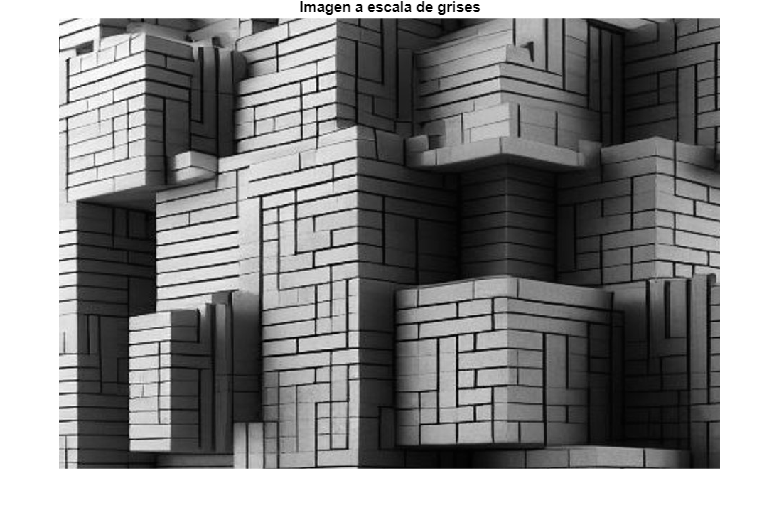

% Cargamos la imagen 
I = rgb2gray(imread('./Imagenes/ladrillos1.jpg'));

figure, imshow(I); title('Imagen a escala de grises');

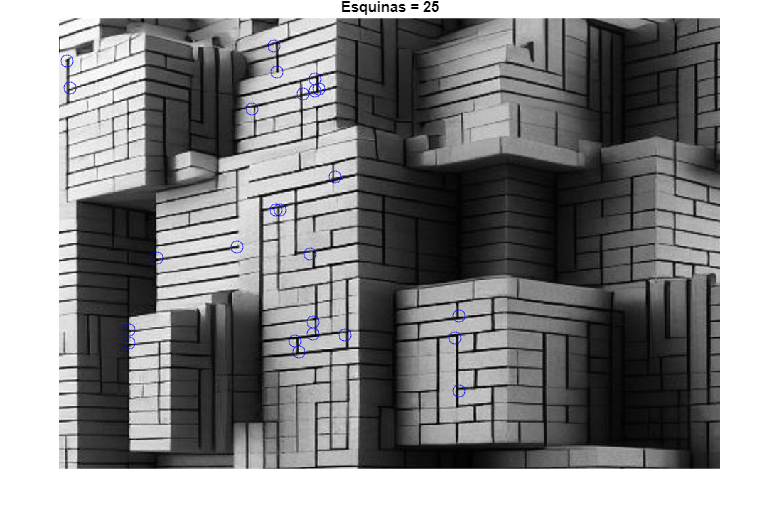

% Identificamos las equinas del objeto de la imagen
corners = detectFASTFeatures(I);
puntos1 = corners.selectStrongest(25);
puntos2 = corners.selectStrongest(200);

% Mostramos las esquinas 
figure;
imshow(I);
hold on;
plot(puntos1.Location(:, 1), puntos1.Location(:, 2), 'bo', 'MarkerSize', 9);
title(sprintf('Esquinas = %d', length(puntos1)));
hold off;

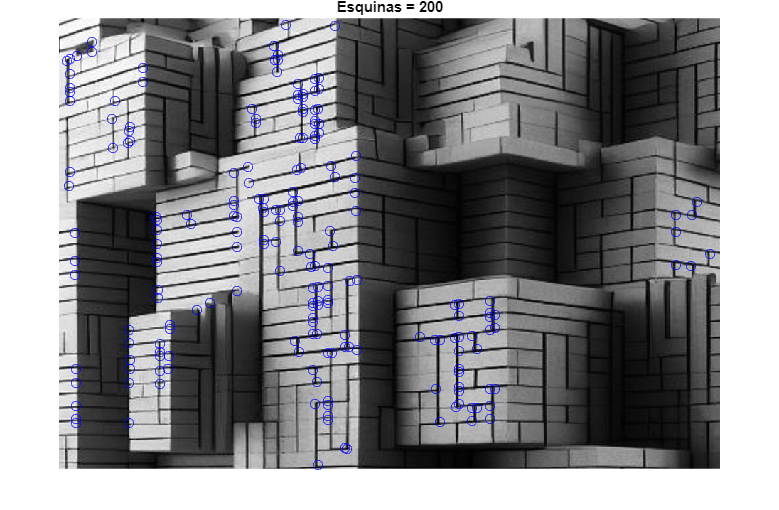

figure;
imshow(I);
hold on;
plot(puntos2.Location(:, 1), puntos2.Location(:, 2), 'bo', 'MarkerSize', 7);
title(sprintf('Esquinas = %d', length(puntos2)));
hold off;

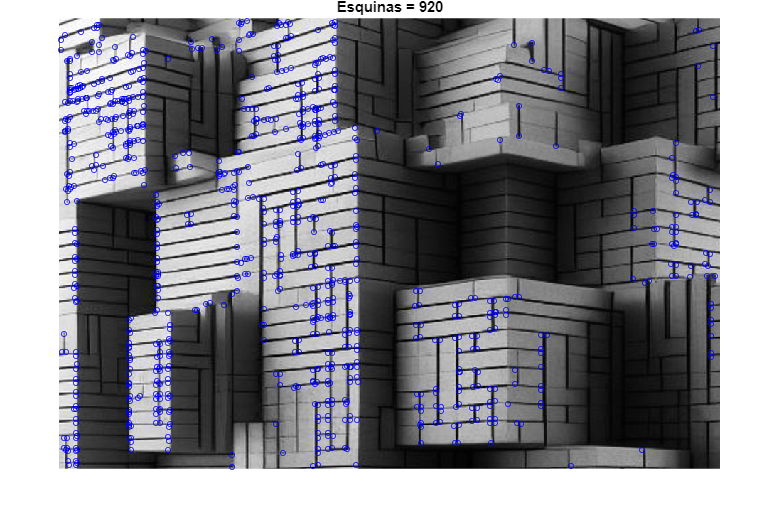

figure;
imshow(I);
hold on;
plot(corners.Location(:, 1), corners.Location(:, 2), 'bo', 'MarkerSize', 4);
title(sprintf('Esquinas = %d', length(corners)));
hold off;

**Comentarios:**

- En los resultados obtenidos, podemos observar que las esquinas detectadas mediante el algoritmo FAST en la imagen de ladrillos presentan algunas características interesantes. En primer lugar, los 25 puntos más fuertes no corresponden a las intersecciones entre los ladrillos, sino que coinciden con las esquinas individuales de cada ladrillo. Luego, al mostrar el resto de los puntos, observamos que algunos indican la posición de esquinas donde no las hay. Este fenómeno es evidente en la última imagen, donde en la esquina superior izquierda se agrupan marcas que no representan esquinas reales.

- Además, se nota que en las áreas más sombreadas de la imagen, el algoritmo no ha identificado ninguna esquina. Este comportamiento podría deberse a la falta de contraste o a la presencia de sombras que afectan la detección de esquinas. Por lo que deducimos que es importante tener en cuenta las situaciones de iluminación variada o áreas con falta de contraste.

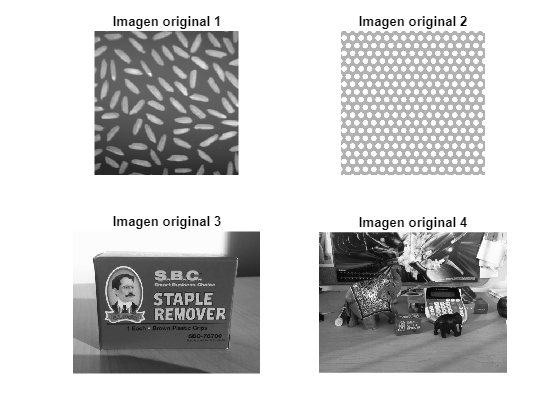

% Probamos con diferentes imagenes el proceso anterior
I = {imread('./Imagenes/rice.tif'), ...
    imread('./Imagenes/texture-pattern2.png'), ...
    imread('./Imagenes/stapleRemover.jpg'), ...
    imread('./Imagenes/clutteredDesk.jpg')};

figure,
for i = 1:length(I)
    subplot(2,2,i), imshow(I{i}); title(sprintf('Imagen original %d', i));
end

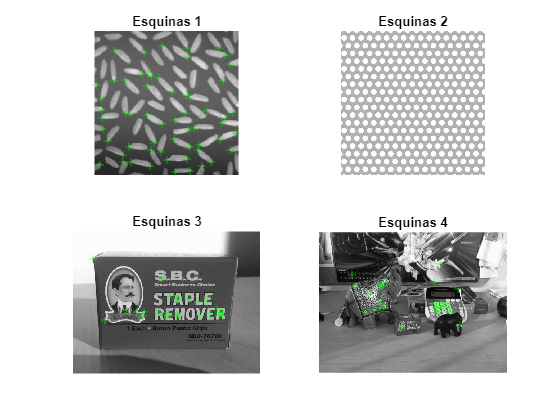

% Identificamos las equinas del objeto de la imagen
corners = {detectFASTFeatures(I{1}), ...
    detectFASTFeatures(I{2}), ...
    detectFASTFeatures(I{3}).selectStrongest(30), ...
    detectFASTFeatures(I{4}).selectStrongest(30)};

% Mostramos las esquinas encontradas en cada imagen
figure, 

for i = 1:4
    subplot(2,2,i), imshow(I{i}); title(sprintf('Esquinas %d', i));
    hold on,
    plot(corners{i});
    hold off;
end

**Comentarios:**

- Tras realizar nuestras observaciones, destacamos inicialmente que en la imagen 2, caracterizada por un patrón circular, no se detectaron esquinas. A partir de esto, podemos concluir que el algoritmo no resulta eficaz para identificar esquinas en patrones circulares. En relación con la imagen 1, que representa granos de arroz, observamos que se detectan algunos puntos de cada grano como esquinas, especialmente aquellos con formas menos arqueadas. En cuanto a la imagen 3, que representa una caja, notamos que al resaltar una cantidad de puntos más fuertes, no se enfocan necesariamente en las esquinas de las cajas como características principales. En su lugar, resaltan detalles de la imagen que contienen bordes con mayor contraste dentro de la caja. Por último, en la última imagen, notamos que se detectan puntos muy específicos como esquinas, dando prioridad a aquellos puntos más particulares en lugar de los más generales de la imagen.

- En resumen, podemos afirmar que el algoritmo es útil en imágenes que presentan patrones con esquinas o en situaciones donde es necesario resaltar características locales.

## Uso de características LBP para distinguir imágenes con texturas diferentes

El objetivo de este ejercicio es verificar el comportamiento de las caracteristicas LBP en imágenes con texturas diferentes. Para ello:

- Abra y muestre las imágenes texture-canvas.png, gotas.jpg, ladrillos2.jpg, ladrillos3.jpg y ladrillos4.jpg y calcule sus características LBP con la instrucción `LBPImag1 = extractLBPFeatures(Imag1,'Upright',false).`

imfinfo('./Imagenes/texture-canvas.png').ColorType

ans = 'grayscale'

imfinfo('./Imagenes/gotas.jpg').ColorType

ans = 'truecolor'

imfinfo('./Imagenes/ladrillos2.jpg').ColorType

ans = 'truecolor'

imfinfo('./Imagenes/ladrillos3.jpg').ColorType

ans = 'truecolor'

imfinfo('./Imagenes/ladrillos4.jpg').ColorType

ans = 'truecolor'

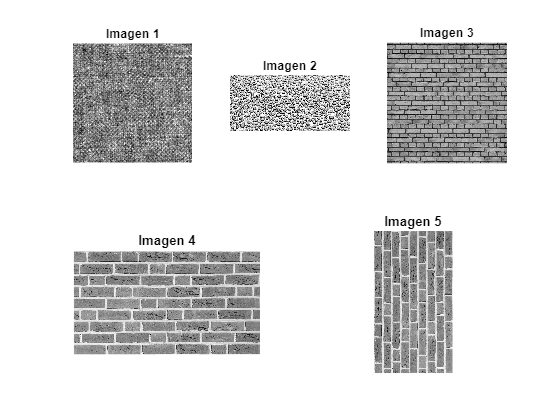

% Cargamos las imagenes
Imag = {imread('./Imagenes/texture-canvas.png'), ...
    rgb2gray(imread('./Imagenes/gotas.jpg')), ...
    rgb2gray(imread('./Imagenes/ladrillos2.jpg')), ...
    rgb2gray(imread('./Imagenes/ladrillos3.jpg')), ...
    rgb2gray(imread('./Imagenes/ladrillos4.jpg'))};

figure,
subplot(2,3,1), imshow(Imag{1}); title('Imagen 1');
subplot(2,3,2), imshow(Imag{2}); title('Imagen 2');
subplot(2,3,3), imshow(Imag{3}); title('Imagen 3');
subplot(2,2,3), imshow(Imag{4}); title('Imagen 4');
subplot(2,2,4), imshow(Imag{5}); title('Imagen 5');

% Reservamos memoria
LBPImag = cell(1, 5);

% Calculamos las caracteristicas
for i = 1:5
    LBPImag{i} = extractLBPFeatures(Imag{i}, 'Upright', false);
end

- Visualice las características con `bar(LBPImag1)`. ¿Se parecen entre sí las características de las distintas imágenes?

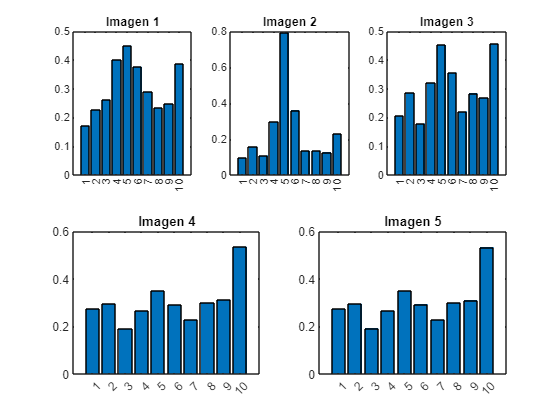

% Visualizamos las caracteristicas
figure,
subplot(2,3,1), bar(LBPImag{1}); title('Imagen 1');
subplot(2,3,2), bar(LBPImag{2}); title('Imagen 2');
subplot(2,3,3), bar(LBPImag{3}); title('Imagen 3');
subplot(2,2,3), bar(LBPImag{4}); title('Imagen 4');
subplot(2,2,4), bar(LBPImag{5}); title('Imagen 5');

- Calcule la distancia entre las características LBP de ladrillos3.jpg y cada una de las demás imágenes, utilizando la instrucción `DistImag1_2 = norm (LBPImag1 - LBPImag2)`. Analice los resultados. ¿Son coherentes con lo que se puede verificar visualmente?

% Calculamos las distancias de ladrillos3 al resto
DistImag4_1 = norm (LBPImag{4} - LBPImag{1})

DistImag4_1 = single
0.2995

DistImag4_2 = norm (LBPImag{4} - LBPImag{2})

DistImag4_2 = single
0.6500

DistImag4_3 = norm (LBPImag{4} - LBPImag{3})

DistImag4_3 = single
0.1753

DistImag4_5 = norm (LBPImag{4} - LBPImag{5})

DistImag4_5 = single
0.0040

**Comentarios:**

- Observamos que los resultados obtenidos son coherentes, notamos que cuanto menor es la distancia entre las características de las imágenes, mayor es su parecido. Comparando las imágenes 4 y 5, identificamos que comparten el mismo patrón, aunque uno está rotado, y observamos que, incluso así, existe una pequeña diferencia. Sin embargo, con el resto de las imágenes, la diferencia se incrementa notablemente. En particular, entre la imagen 2 y la 4, la distancia es considerablemente grande, tanto en el gráfico de barras de las características como en las propias imágenes, donde no se aprecia ningún parecido.

- Este enfoque puede ser especialmente útil para diferenciar distintos tipos de texturas de objetos, ya sea dentro de la misma imagen o entre imágenes diferentes.